clc

%import and prepare data%
%By the way,in order to fit in the format of matrix, year 2016.2017 was omitted
%intentionly.%
raw_data=xlsread('D:\all study and no paly make Jack a dull boy\2021 春\Corporate Finance\Case Analysis-APC\Solution\Product analysis.xlsx',1)

raw_data = 	1.0e+07 *

         0    0.0000    0.0002       NaN       NaN       NaN       NaN    3.5100       NaN       NaN       NaN       NaN    0.0414       NaN         0   -3.5100    3.9000       NaN       NaN   -3.5100   -3.5100       NaN       NaN
    0.0000    0.0000    0.0002    0.0020    0.0000    0.7140    0.1428    0.3900    0.1560    0.4152    0.2076    0.3636    0.0426    0.0012    0.3624   -0.0276    3.7440       NaN       NaN   -0.0276   -0.0254       NaN       NaN
    0.0000    0.0000    0.0002    0.0020    0.0000    0.7211    0.1485         0    0.1560    0.4166    0.2083    0.3643    0.0439    0.0013    0.3630    0.3630    3.5880       NaN       NaN    0.3630    0.3056       NaN       NaN
    0.0000    0.0000    0.0002    0.0020    0.0000    0.7283    0.1545         0    0.1560    0.4178    0.2089    0.3649    0.0452    0.0013    0.3636    0.3636    3.4320       NaN       NaN    0.3636    0.2808       NaN       NaN
    0.0000    0.0000    0.0002    0.0019    0.0000   

filename='D:\all study and no paly make Jack a dull boy\2021 春\Corporate Finance\Case Analysis-APC\Solution\1.xlsx'

filename = 'D:\all study and no paly make Jack a dull boy\2021 春\Corporate Finance\Case Analysis-APC\Solution\1.xlsx'

%replace nan by number 0, so that we can use the data more easily%
raw_data(isnan(raw_data)) = 0 

raw_data = 	1.0e+07 *

         0    0.0000    0.0002         0         0         0         0    3.5100         0         0         0         0    0.0414         0         0   -3.5100    3.9000         0         0   -3.5100   -3.5100         0         0
    0.0000    0.0000    0.0002    0.0020    0.0000    0.7140    0.1428    0.3900    0.1560    0.4152    0.2076    0.3636    0.0426    0.0012    0.3624   -0.0276    3.7440         0         0   -0.0276   -0.0254         0         0
    0.0000    0.0000    0.0002    0.0020    0.0000    0.7211    0.1485         0    0.1560    0.4166    0.2083    0.3643    0.0439    0.0013    0.3630    0.3630    3.5880         0         0    0.3630    0.3056         0         0
    0.0000    0.0000    0.0002    0.0020    0.0000    0.7283    0.1545         0    0.1560    0.4178    0.2089    0.3649    0.0452    0.0013    0.3636    0.3636    3.4320         0         0    0.3636    0.2808         0         0
    0.0000    0.0000    0.0002    0.0019    0.0000   

%Rename the data using corporate financial terminology%
age=raw_data(:,1)

age =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


revenue=raw_data(:,6)

revenue =            0
     7140000
     7211400
     7282800
     6680898
     6170031
     6170793
     6241746
     6313758
     6386476


operating_cost=raw_data(:,7)

operating_cost = 	1.0e+06 *

         0
    1.4280
    1.4851
    1.5445
    1.6063
    1.6706
    1.7179
    1.7866
    1.8581
    1.9324


CAPX=raw_data(:,8)

CAPX =     35100000
     3900000
           0
           0
           0
       60000
       60000
       60000
       60000
       60000


DEPR=raw_data(:,9)

DEPR =            0
     1560000
     1560000
     1560000
     1560000
     1560000
     1560000
     1560000
     1560000
     1560000


EBIT=raw_data(:,10)

EBIT = 	1.0e+06 *

         0
    4.1520
    4.1663
    4.1783
    3.5146
    2.9395
    2.8929
    2.8951
    2.8957
    2.8941


EBIAT=raw_data(:,11)

EBIAT = 	1.0e+06 *

         0
    2.0760
    2.0831
    2.0891
    1.7573
    1.4697
    1.4464
    1.4476
    1.4478
    1.4470


change_in_nwc=raw_data(:,14)

change_in_nwc = 	1.0e+05 *

         0
    0.1241
    0.1278
    0.1316
    0.1356
    0.1396
    0.1438
    0.1481
    0.1526
    0.1572


FCF=raw_data(:,20)

FCF = 	1.0e+07 *

   -3.5100
   -0.0276
    0.3630
    0.3636
    0.3304
    0.2956
    0.2932
    0.2933
    0.2933
    0.2931


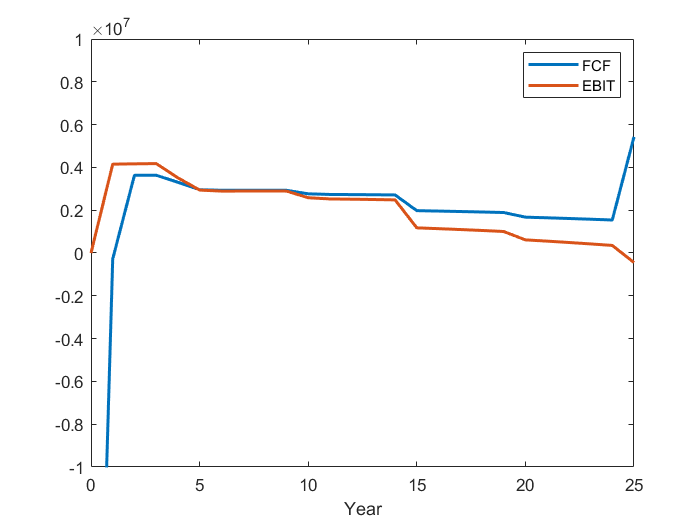

%FCF,EBIT,%
plot(age,FCF,'LineWidth',1.8)
hold on
plot(age,EBIT,'LineWidth',1.8)

xlim([0.0 25.0])
ylim([-10000000 10000000])
legend({'FCF','EBIT'})
xlabel('Year')
hold off

%sesitive analysis%

ii=0

ii = 0

jj=0

jj = 0

for i=300:5:365
    ii=ii+1
    for j=1:0.01:1.1
    jj=jj+1
    tester=xlswrite(filename,i,2,'B6')
    tester=xlswrite(filename,i,2,'H11')
    
    NPV_sen_i(ii,jj)=xlsread(filename,1,'W27')
    end
    jj=0
end

ii = 1

jj = 1

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    1.4248    1.4248    1.4248    1.4248    1.4248    1.4248    1.4248    1.4248    1.4248    1.4248
    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654


jj = 2

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    1.4248    1.4248    1.4248    1.4248    1.4248    1.4248    1.4248    1.4248    1.4248
    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654


jj = 3

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    1.4248    1.4248    1.4248    1.4248    1.4248    1.4248    1.4248    1.4248
    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654


jj = 4

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    1.4248    1.4248    1.4248    1.4248    1.4248    1.4248    1.4248
    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654


jj = 5

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    1.4248    1.4248    1.4248    1.4248    1.4248    1.4248
    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654


jj = 6

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    1.4248    1.4248    1.4248    1.4248    1.4248
    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654


jj = 7

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    1.4248    1.4248    1.4248    1.4248
    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654


jj = 8

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    1.4248    1.4248    1.4248
    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654


jj = 9

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    1.4248    1.4248
    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654


jj = 10

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    1.4248
    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654


jj = 11

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654


jj = 0

ii = 2

jj = 1

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654


jj = 2

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654


jj = 3

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654


jj = 4

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654


jj = 5

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.4654    1.4654    1.4654    1.4654    1.4654    1.4654


jj = 6

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.4654    1.4654    1.4654    1.4654    1.4654


jj = 7

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.4654    1.4654    1.4654    1.4654


jj = 8

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.4654    1.4654    1.4654


jj = 9

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.4654    1.4654


jj = 10

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.4654


jj = 11

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154


jj = 0

ii = 3

jj = 1

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498         0         0         0         0         0         0         0         0         0         0


jj = 2

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498         0         0         0         0         0         0         0         0         0


jj = 3

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498         0         0         0         0         0         0         0         0


jj = 4

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498         0         0         0         0         0         0         0


jj = 5

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498         0         0         0         0         0         0


jj = 6

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498         0         0         0         0         0


jj = 7

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498         0         0         0         0


jj = 8

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498         0         0         0


jj = 9

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498         0         0


jj = 10

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498         0


jj = 11

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498


jj = 0

ii = 4

jj = 1

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847         0         0         0         0         0         0         0         0         0         0


jj = 2

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847         0         0         0         0         0         0         0         0         0


jj = 3

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847         0         0         0         0         0         0         0         0


jj = 4

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847         0         0         0         0         0         0         0


jj = 5

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847         0         0         0         0         0         0


jj = 6

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847         0         0         0         0         0


jj = 7

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847         0         0         0         0


jj = 8

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847         0         0         0


jj = 9

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847         0         0


jj = 10

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847         0


jj = 11

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847


jj = 0

ii = 5

jj = 1

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202         0         0         0         0         0         0         0         0         0         0


jj = 2

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202         0         0         0         0         0         0         0         0         0


jj = 3

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202         0         0         0         0         0         0         0         0


jj = 4

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202         0         0         0         0         0         0         0


jj = 5

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202         0         0         0         0         0         0


jj = 6

tester = logical
   1


tester = logical
   1


NPV_sen_i = 	1.0e+10 *

    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202         0         0         0         0         0


jj = 7

tester = logical
   1


tester = logical
   1


NPV_sen_i = 5×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202         0         0         0         0


jj = 8

tester = logical
   1


tester = logical
   1


NPV_sen_i = 5×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202         0         0         0


jj = 9

tester = logical
   1


tester = logical
   1


NPV_sen_i = 5×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202         0         0


jj = 10

tester = logical
   1


tester = logical
   1


NPV_sen_i = 5×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202         0


jj = 11

tester = logical
   1


tester = logical
   1


NPV_sen_i = 5×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202


jj = 0

ii = 6

jj = 1

tester = logical
   1


tester = logical
   1


NPV_sen_i = 6×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563         0         0         0         0         0         0         0         0         0         0


jj = 2

tester = logical
   1


tester = logical
   1


NPV_sen_i = 6×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563         0         0         0         0         0         0         0         0         0


jj = 3

tester = logical
   1


tester = logical
   1


NPV_sen_i = 6×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563         0         0         0         0         0         0         0         0


jj = 4

tester = logical
   1


tester = logical
   1


NPV_sen_i = 6×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563         0         0         0         0         0         0         0


jj = 5

tester = logical
   1


tester = logical
   1


NPV_sen_i = 6×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563         0         0         0         0         0         0


jj = 6

tester = logical
   1


tester = logical
   1


NPV_sen_i = 6×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563         0         0         0         0         0


jj = 7

tester = logical
   1


tester = logical
   1


NPV_sen_i = 6×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563         0         0         0         0


jj = 8

tester = logical
   1


tester = logical
   1


NPV_sen_i = 6×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563         0         0         0


jj = 9

tester = logical
   1


tester = logical
   1


NPV_sen_i = 6×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563         0         0


jj = 10

tester = logical
   1


tester = logical
   1


NPV_sen_i = 6×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563         0


jj = 11

tester = logical
   1


tester = logical
   1


NPV_sen_i = 6×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563


jj = 0

ii = 7

jj = 1

tester = logical
   1


tester = logical
   1


NPV_sen_i = 7×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930         0         0         0         0         0         0         0         0         0         0


jj = 2

tester = logical
   1


tester = logical
   1


NPV_sen_i = 7×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930         0         0         0         0         0         0         0         0         0


jj = 3

tester = logical
   1


tester = logical
   1


NPV_sen_i = 7×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930         0         0         0         0         0         0         0         0


jj = 4

tester = logical
   1


tester = logical
   1


NPV_sen_i = 7×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930         0         0         0         0         0         0         0


jj = 5

tester = logical
   1


tester = logical
   1


NPV_sen_i = 7×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930         0         0         0         0         0         0


jj = 6

tester = logical
   1


tester = logical
   1


NPV_sen_i = 7×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930         0         0         0         0         0


jj = 7

tester = logical
   1


tester = logical
   1


NPV_sen_i = 7×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930         0         0         0         0


jj = 8

tester = logical
   1


tester = logical
   1


NPV_sen_i = 7×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930         0         0         0


jj = 9

tester = logical
   1


tester = logical
   1


NPV_sen_i = 7×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930         0         0


jj = 10

tester = logical
   1


tester = logical
   1


NPV_sen_i = 7×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930         0


jj = 11

tester = logical
   1


tester = logical
   1


NPV_sen_i = 7×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930


jj = 0

ii = 8

jj = 1

tester = logical
   1


tester = logical
   1


NPV_sen_i = 8×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302         0         0         0         0         0         0         0         0         0         0


jj = 2

tester = logical
   1


tester = logical
   1


NPV_sen_i = 8×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302         0         0         0         0         0         0         0         0         0


jj = 3

tester = logical
   1


tester = logical
   1


NPV_sen_i = 8×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302         0         0         0         0         0         0         0         0


jj = 4

tester = logical
   1


tester = logical
   1


NPV_sen_i = 8×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302         0         0         0         0         0         0         0


jj = 5

tester = logical
   1


tester = logical
   1


NPV_sen_i = 8×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302         0         0         0         0         0         0


jj = 6

tester = logical
   1


tester = logical
   1


NPV_sen_i = 8×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302         0         0         0         0         0


jj = 7

tester = logical
   1


tester = logical
   1


NPV_sen_i = 8×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302         0         0         0         0


jj = 8

tester = logical
   1


tester = logical
   1


NPV_sen_i = 8×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302         0         0         0


jj = 9

tester = logical
   1


tester = logical
   1


NPV_sen_i = 8×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302         0         0


jj = 10

tester = logical
   1


tester = logical
   1


NPV_sen_i = 8×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302         0


jj = 11

tester = logical
   1


tester = logical
   1


NPV_sen_i = 8×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302


jj = 0

ii = 9

jj = 1

tester = logical
   1


tester = logical
   1


NPV_sen_i = 9×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680         0         0         0         0         0         0         0         0     

jj = 2

tester = logical
   1


tester = logical
   1


NPV_sen_i = 9×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680         0         0         0         0         0         0         0     

jj = 3

tester = logical
   1


tester = logical
   1


NPV_sen_i = 9×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680         0         0         0         0         0         0     

jj = 4

tester = logical
   1


tester = logical
   1


NPV_sen_i = 9×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680         0         0         0         0         0     

jj = 5

tester = logical
   1


tester = logical
   1


NPV_sen_i = 9×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680         0         0         0         0     

jj = 6

tester = logical
   1


tester = logical
   1


NPV_sen_i = 9×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680         0         0         0     

jj = 7

tester = logical
   1


tester = logical
   1


NPV_sen_i = 9×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680         0         0     

jj = 8

tester = logical
   1


tester = logical
   1


NPV_sen_i = 9×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680         0     

jj = 9

tester = logical
   1


tester = logical
   1


NPV_sen_i = 9×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680     

jj = 10

tester = logical
   1


tester = logical
   1


NPV_sen_i = 9×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1

jj = 11

tester = logical
   1


tester = logical
   1


NPV_sen_i = 9×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1

jj = 0

ii = 10

jj = 1

tester = logical
   1


tester = logical
   1


NPV_sen_i = 10×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 2

tester = logical
   1


tester = logical
   1


NPV_sen_i = 10×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 3

tester = logical
   1


tester = logical
   1


NPV_sen_i = 10×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 4

tester = logical
   1


tester = logical
   1


NPV_sen_i = 10×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 5

tester = logical
   1


tester = logical
   1


NPV_sen_i = 10×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 6

tester = logical
   1


tester = logical
   1


NPV_sen_i = 10×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 7

tester = logical
   1


tester = logical
   1


NPV_sen_i = 10×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 8

tester = logical
   1


tester = logical
   1


NPV_sen_i = 10×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 9

tester = logical
   1


tester = logical
   1


NPV_sen_i = 10×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 10

tester = logical
   1


tester = logical
   1


NPV_sen_i = 10×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 11

tester = logical
   1


tester = logical
   1


NPV_sen_i = 10×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 0

ii = 11

jj = 1

tester = logical
   1


tester = logical
   1


NPV_sen_i = 11×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 2

tester = logical
   1


tester = logical
   1


NPV_sen_i = 11×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 3

tester = logical
   1


tester = logical
   1


NPV_sen_i = 11×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 4

tester = logical
   1


tester = logical
   1


NPV_sen_i = 11×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 5

tester = logical
   1


tester = logical
   1


NPV_sen_i = 11×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 6

tester = logical
   1


tester = logical
   1


NPV_sen_i = 11×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 7

tester = logical
   1


tester = logical
   1


NPV_sen_i = 11×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 8

tester = logical
   1


tester = logical
   1


NPV_sen_i = 11×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 9

tester = logical
   1


tester = logical
   1


NPV_sen_i = 11×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 10

tester = logical
   1


tester = logical
   1


NPV_sen_i = 11×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 11

tester = logical
   1


tester = logical
   1


NPV_sen_i = 11×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 0

ii = 12

jj = 1

tester = logical
   1


tester = logical
   1


NPV_sen_i = 12×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 2

tester = logical
   1


tester = logical
   1


NPV_sen_i = 12×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 3

tester = logical
   1


tester = logical
   1


NPV_sen_i = 12×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 4

tester = logical
   1


tester = logical
   1


NPV_sen_i = 12×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 5

tester = logical
   1


tester = logical
   1


NPV_sen_i = 12×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 6

tester = logical
   1


tester = logical
   1


NPV_sen_i = 12×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 7

tester = logical
   1


tester = logical
   1


NPV_sen_i = 12×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 8

tester = logical
   1


tester = logical
   1


NPV_sen_i = 12×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 9

tester = logical
   1


tester = logical
   1


NPV_sen_i = 12×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 10

tester = logical
   1


tester = logical
   1


NPV_sen_i = 12×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 11

tester = logical
   1


tester = logical
   1


NPV_sen_i = 12×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 0

ii = 13

jj = 1

tester = logical
   1


tester = logical
   1


NPV_sen_i = 13×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 2

tester = logical
   1


tester = logical
   1


NPV_sen_i = 13×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 3

tester = logical
   1


tester = logical
   1


NPV_sen_i = 13×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 4

tester = logical
   1


tester = logical
   1


NPV_sen_i = 13×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 5

tester = logical
   1


tester = logical
   1


NPV_sen_i = 13×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 6

tester = logical
   1


tester = logical
   1


NPV_sen_i = 13×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 7

tester = logical
   1


tester = logical
   1


NPV_sen_i = 13×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 8

tester = logical
   1


tester = logical
   1


NPV_sen_i = 13×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 9

tester = logical
   1


tester = logical
   1


NPV_sen_i = 13×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 10

tester = logical
   1


tester = logical
   1


NPV_sen_i = 13×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 11

tester = logical
   1


tester = logical
   1


NPV_sen_i = 13×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 0

ii = 14

jj = 1

tester = logical
   1


tester = logical
   1


NPV_sen_i = 14×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 2

tester = logical
   1


tester = logical
   1


NPV_sen_i = 14×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 3

tester = logical
   1


tester = logical
   1


NPV_sen_i = 14×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 4

tester = logical
   1


tester = logical
   1


NPV_sen_i = 14×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 5

tester = logical
   1


tester = logical
   1


NPV_sen_i = 14×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 6

tester = logical
   1


tester = logical
   1


NPV_sen_i = 14×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 7

tester = logical
   1


tester = logical
   1


NPV_sen_i = 14×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 8

tester = logical
   1


tester = logical
   1


NPV_sen_i = 14×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 9

tester = logical
   1


tester = logical
   1


NPV_sen_i = 14×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 10

tester = logical
   1


tester = logical
   1


NPV_sen_i = 14×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 11

tester = logical
   1


tester = logical
   1


NPV_sen_i = 14×11
    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817    0.9817
    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154    1.0154
    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498    1.0498
    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847    1.0847
    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202    1.1202
    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563    1.1563
    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930    1.1930
    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302    1.2302
    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    1.2680    

jj = 0

i=300:5:365

i =    360   365


j=1:0.01:1.1

j =     1.0000    1.0100    1.0200    1.0300    1.0400    1.0500    1.0600    1.0700    1.0800    1.0900    1.1000


mesh(i,j',NPV_sen_i)

错误使用 mesh (第 71 行)
数据维度必须一致。